m = 30;
g = 9.81;
L = 2.5;
mu = 7;

# No Control Input

Our first simulation will consider the case $u\left(t\right)=0$

u = @(t) 0;

We solve the differential equation for the initial conditions $x\left(0\right)=\left\lbrack \;\ldotp 9\pi \;\;0\right\rbrack$

[t,x] = ode45(@(t,x) swing(x,u(t),m,g,L,mu),[0 60],[.9*pi 0]);

We now plot $\theta \left(t\right)$

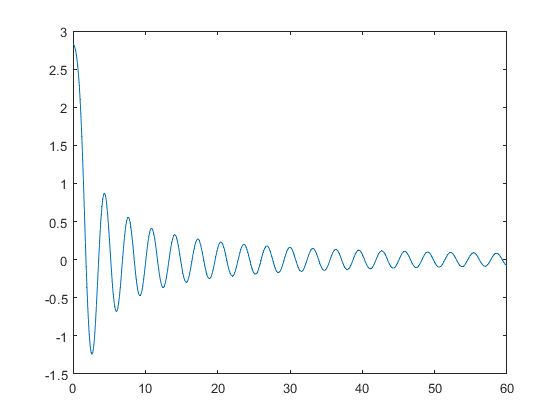

plot(t,x(:,1))

We an also plot the behavior in the phase plane: $\theta$ vs $\dot{\theta}$

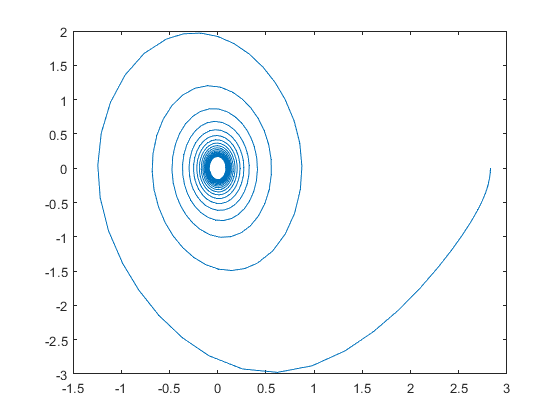

plot(x(:,1),x(:,2))

Intuitively, we note that the system is losing energy over time. In our case, the energy is the sum of potential energy plus kinetic energy


$$E=mgL\left(1-\cos \left(\theta \right)\right)+\frac{1}{2}{mL}^2 \;{\dot{\theta} }^{\;2}$$


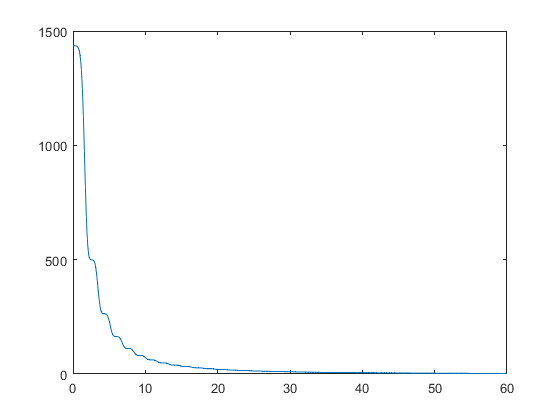

E = m*g*L*(1-cos(x(:,1)))+1/2*m*L^2*x(:,2).^2;
plot(t,E)

Although we plotted the energy as a function of time, we can also compute the energy in each point of the phase plane. To this end, we're going to create a grid for $\theta \in \left\lbrack -2\pi ,2\pi \right\rbrack$ and $\dot{\theta} \in \left\lbrack -3,3\right\rbrack$. 

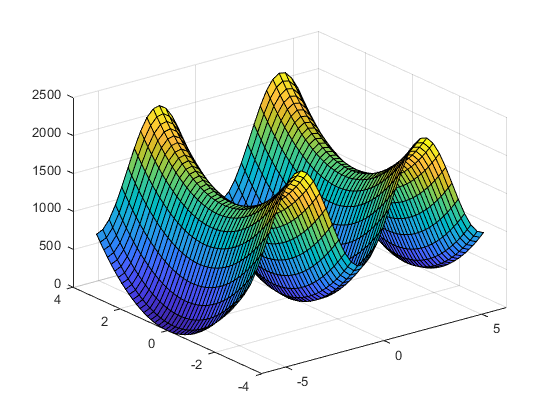

[X,Y] = meshgrid(linspace(-2*pi,2*pi,40),linspace(-3,3,40));

E = m*g*L*(1-cos(X)) + 1/2*m*L^2*Y.^2;

surf(X,Y,E)

Looking at the contour plot, we can now see that the trajectories of the system go from higher energy level-sets to lower level-sets.

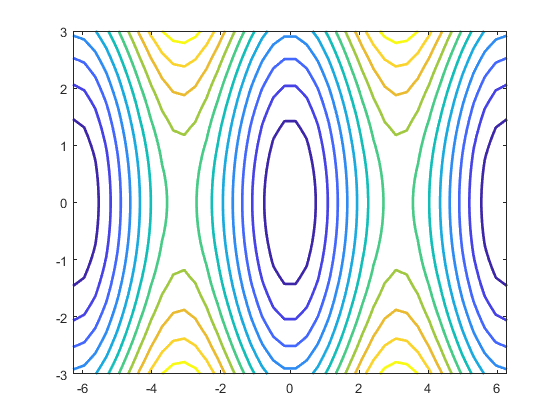

contour(X,Y,E,'LineWidth',2)
hold on

% Uncomment to See Comet
% comet(x(:,1),x(:,2),0.99)
hold off

# With Control Input

We now look at the case where the person on the swing is movint their legs at a given frequency $\omega$. In this case, we are going to excite the system at its resonant frequency 

$\omega =\sqrt{\frac{g}{L}}$. 

Any other frequency will not swing as high.

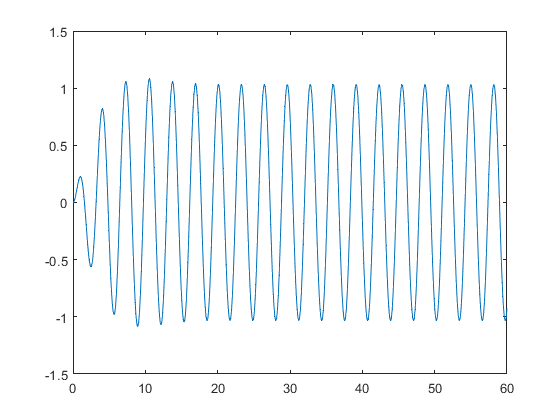

w = sqrt(g/L);
u = @(t) m*L^2*cos(w*t);

[t,x] = ode45(@(t,x) swing(x,u(t),m,g,L,mu),[0 60],[0 0]);

plot(t,x(:,1))

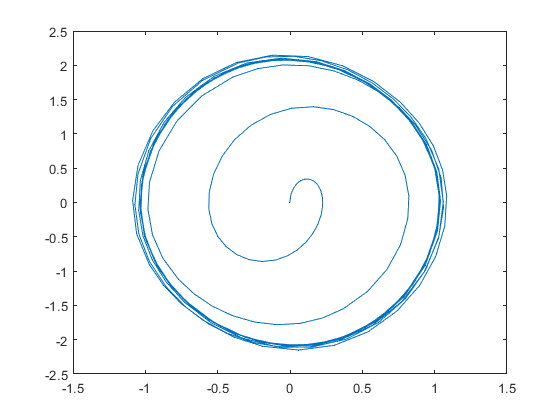


plot(x(:,1),x(:,2))

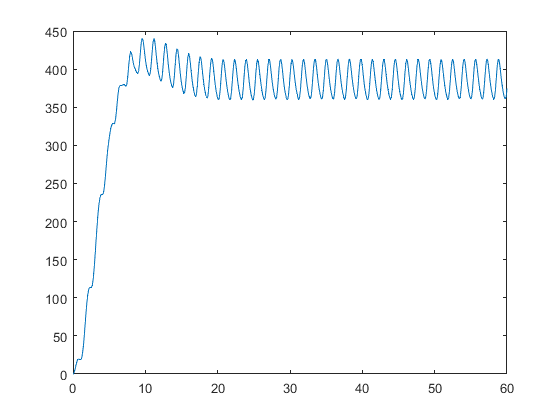


E = m*g*L*(1-cos(x(:,1)))+1/2*m*L^2*x(:,2).^2;
plot(t,E)

[X,Y] = meshgrid(linspace(-2*pi,2*pi,40),linspace(-3,3,40));

E = m*g*L*(1-cos(X)) + 1/2*m*L^2*Y.^2;

surf(X,Y,E)

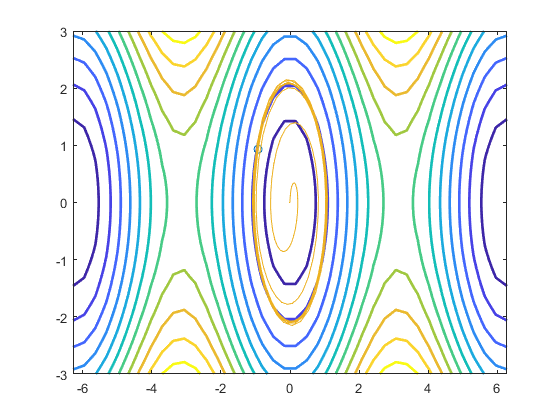


contour(X,Y,E,'LineWidth',2)
hold on

comet(x(:,1),x(:,2),0.99)

# Pendulum Dynamics

The dynamic model we wish to solve is


$$mL^2 \;\ddot{\theta \;} =-mgL\;\sin \left(\theta \right)-\mu L^2 \left\|\dot{\theta} \right\|\dot{\theta} +u\left(t\right)$$


To formulate it in terms that MATLAB would undestand, we need to tun it into someting that looks like a first order equation


$$\dot{x} =f\left(t,x\right)$$


where $x$ is a **vector**. The size of $x$ needs to be the same as the order of the differential equation. In this case, 2. Thus, we assign


$$x=\left\lbrack \begin{array}{c}
\theta \\
\dot{\theta} 
\end{array}\right\rbrack$$


and compute


$$\dot{x} =\left\lbrack \begin{array}{c}
\dot{\theta} \\
\ddot{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{\theta} \\
-\frac{g}{L}\;\sin \left(\theta \right)-\frac{\mu }{m}\left\|\dot{\theta} \right\|\dot{\theta} +\frac{1}{{mL}^2 }u\left(t\right)
\end{array}\right\rbrack$$


function dx = swing(x,u,m,g,L,mu)

dx = [ x(2)
       -g/L*sin(x(1))-mu/m*norm(x(2))*x(2)+1/(m*L^2)*u];

end